clear all; clc;
pos_x = x(x > 0); % Selects positive elements from vector x

element = my_list(index);
sub_list = my_list(start_index:end_index);
n = length(vector);


## unique elements 

clear all; clc;
% for unique elements (pseudo-code, needs implementation)
unique_elements = [];
for i = 1:length(input_list)
    if ~ismember(input_list(i), unique_elements)
    unique_elements = [unique_elements, input_list(i)];
    end
end

## % Matrices:

clear all; clc;
A = [1 2 3; 2 4 5; 3 5 6]; % Symmetric matrix example
B = [1 2 3; 4 5 6; 3 2 1]; % Non-symmetric matrix example

B = transpose(A); % B = A'

% MATRIX IS SYMMATRIC ??

if A == B % Element-wise comparison, returns logical matrix
    disp('Matrices are equal (element-wise)');
end

if isequal(A, A) % Checks if matrices are identical
    disp('Matrix is symmetric');
end

% MATRIX ADDITION
A = [1 2; 3 4];
B = [5 6; 7 8];
C = A + B;
disp('Sum of matrices is:');
disp(C);

% MEAN of matrix elements:
m = mean(C); % For a matrix, mean operates column-wise by default
% m_all = mean(C, 'all'); % For mean of all elements (R2018b+) 

I = eye(n); % Creates an n x n identity matrix 

% Augmented Matrix: For solving linear systems.
Augmented matrix: [A b] 

% Rank of a matrix:
rank(A);
rank([A b]); % Rank of augmented matrix 

% Reduced Row Echelon Form:
rref(A); 

% LU Decomposition:
[L, U, P] = lu(A); 

% Cell arrays:
names = {'Ali', 'Fatemeh', 'Mohammad', 'Sara', 'Reza'};


## Plots

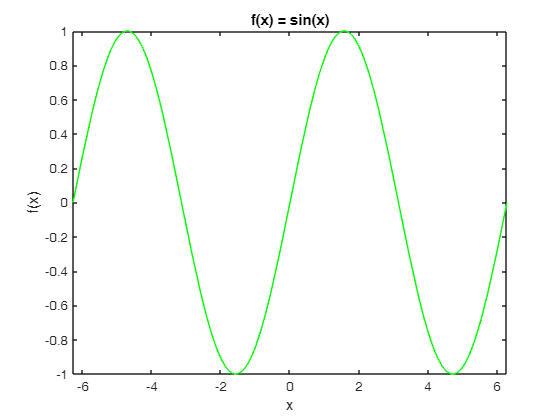

clear all; clc;

% 1. Plotting symbolic functions (fplot)
figure;
syms x_sym
f1 = sin(x_sym);
fplot(f1, [-2*pi, 2*pi], 'g');
xlabel('x');
ylabel('f(x)');
title('f(x) = sin(x)');

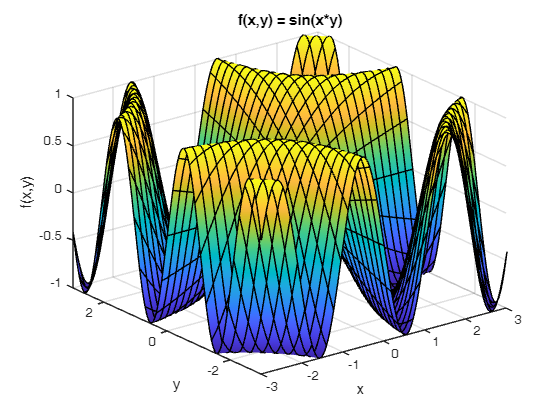


% 2. Plotting 3D surfaces with fsurf
figure;
f2 = @(x, y) sin(x .* y);
fsurf(f2, [-3, 3, -3, 3]);
title('f(x,y) = sin(x*y)');
xlabel('x');
ylabel('y');
zlabel('f(x,y)');

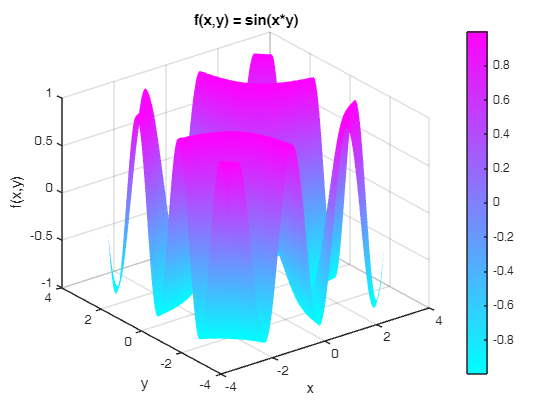


% 3. Plotting 3D surface using meshgrid and surf
figure;
x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);
[X, Y] = meshgrid(x, y);
Z = sin(X .* Y);
surf(X, Y, Z);
title('f(x,y) = sin(x*y)');
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
colormap('cool');
colorbar;
shading interp;

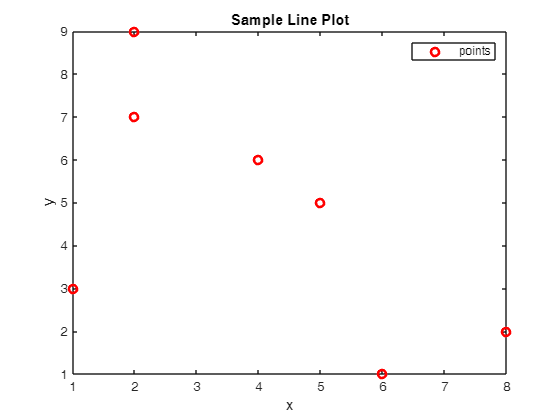


% 4. Plotting multiple points/curve
figure;
x_values = [1, 4, 2, 6, 2, 8, 5];
y_values = [3, 6, 9, 1, 7, 2, 5];
plot(x_values, y_values, 'ro', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Sample Line Plot');
legend('points');

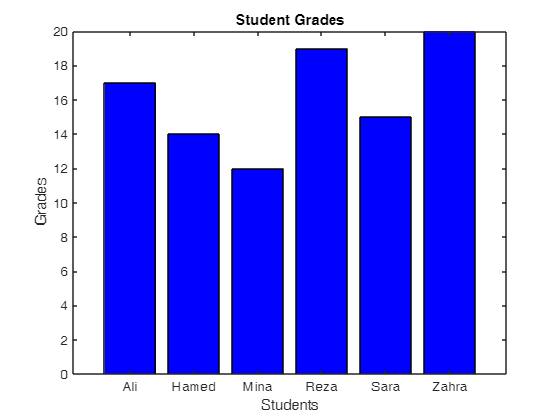


% 5. Bar chart
figure;
grades = [17, 15, 19, 12, 14, 20];
names = {'Ali', 'Sara', 'Reza', 'Mina', 'Hamed', 'Zahra'};
bar(categorical(names), grades, 'b');
xlabel('Students');
ylabel('Grades');
title('Student Grades');

## Equations and Solvin

clear all; clc;

%% Symbolic solving of equations (solve)
syms x
equation = sin(x)^2 - sym(1)/4 == 0;  % ensure symbolic 1/4
solutions = solve(equation, x);
disp('Symbolic solutions:');

Symbolic solutions:


disp(solutions);

$$\left(\begin{array}{c} \frac{\pi }{6}\\ \frac{5\,\pi }{6} \end{array}\right)$$


%% Numerical solving of complex/non-analytical equations (vpasolve)
syms x
f = sin(x)^2 - 1/4;
% Use vpasolve with initial guesses for different roots
root1 = vpasolve(f, x, 0.5); % Initial guess near first root
root2 = vpasolve(f, x, 2.5); % Initial guess near second root
disp('Numerical roots using vpasolve:');

Numerical roots using vpasolve:


disp(root1);

$$0.52359877559829887307710723054658$$

disp(root2); 

$$2.6179938779914943653855361527329$$


%% Solving nonlinear systems (fsolve)
% Requires Optimization Toolbox
% System: sin(x) + y^2 = 2, x^2 + cos(y) = 1
fun = @(z) [sin(z(1)) + z(2)^2 - 2;
            z(1)^2 + cos(z(2)) - 1];
initial_guess = [1; 1];
solution = fsolve(fun, initial_guess);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp('Solution of nonlinear system using fsolve:');

Solution of nonlinear system using fsolve:


disp(solution); 

    0.7652
    1.1434



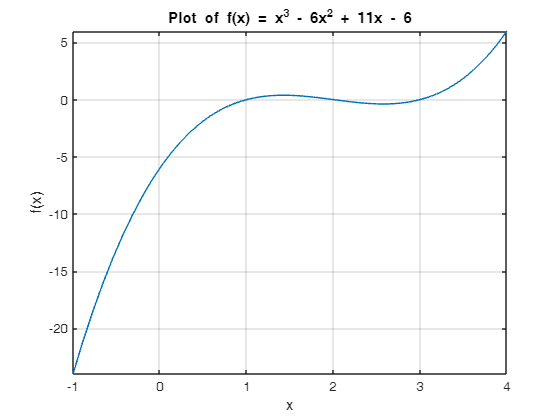


%% Finding roots of a single-variable function (fzero)
% Function: f(x) = x^3 - 6*x^2 + 11*x - 6
f = @(x) x.^3 - 6*x.^2 + 11*x - 6;
% Plot to estimate root locations
figure
fplot(f, [-1, 4]);
grid on;
title('Plot of f(x) = x^3 - 6x^2 + 11x - 6');
xlabel('x'); ylabel('f(x)');


% Use fzero with different initial guesses
root1 = fzero(f, 0.5); % near x=1
root2 = fzero(f, 2.5); % near x=2
root3 = fzero(f, 3.5); % near x=3
disp('Roots using fzero:');

Roots using fzero:


disp([root1, root2, root3]);

    1.0000    2.0000    3.0000



## Functions math

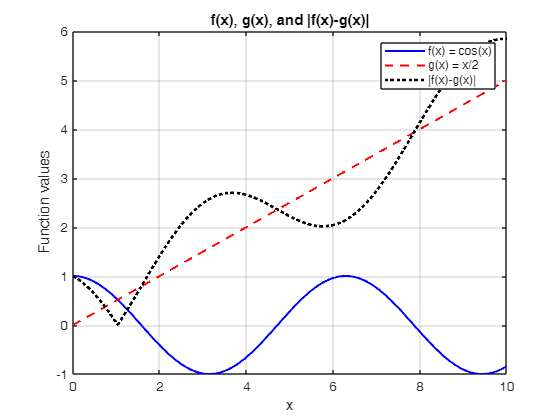

clear all; clc;

f = @(x) cos(x);
g = @(x) x/2;
difference = @(x) abs(f(x) - g(x));

x_plot = linspace(0, 10, 500);
figure;
plot(x_plot, f(x_plot), 'b-', 'LineWidth', 1.5); hold on;
plot(x_plot, g(x_plot), 'r--', 'LineWidth', 1.5);
plot(x_plot, difference(x_plot), 'k:', 'LineWidth', 2);
xlabel('x'); ylabel('Function values');
legend('f(x) = cos(x)', 'g(x) = x/2', '|f(x)-g(x)|', 'Location', 'northeast');
title('f(x), g(x), and |f(x)-g(x)|');
grid on;
hold off;


a = 0; b = 10;
n = 100;
h = (b - a) / n;
x_simpson = a:h:b;
y_simpson = difference(x_simpson);

I_simpson = y_simpson(1) + y_simpson(end);
I_simpson = I_simpson + 4 * sum(y_simpson(2:2:end-1)) + 2 * sum(y_simpson(3:2:end-2));
I_simpson = I_simpson * (h/3);

disp('Simpson''s Rule approximation of ∫ |f(x)-g(x)| dx from 0 to 10:');

Simpson's Rule approximation of ∫ |f(x)-g(x)| dx from 0 to 10:


disp(I_simpson);

   26.7297




I_integral = integral(difference, a, b);
disp('Numeric integral (integral) of |f-g| over [0,10]:');

Numeric integral (integral) of |f-g| over [0,10]:


disp(I_integral);

   26.7282




I_trapz = trapz(x_plot, difference(x_plot));
disp('Numeric integral (trapz) of |f-g| over [0,10]:');

Numeric integral (trapz) of |f-g| over [0,10]:


disp(I_trapz);

   26.7282



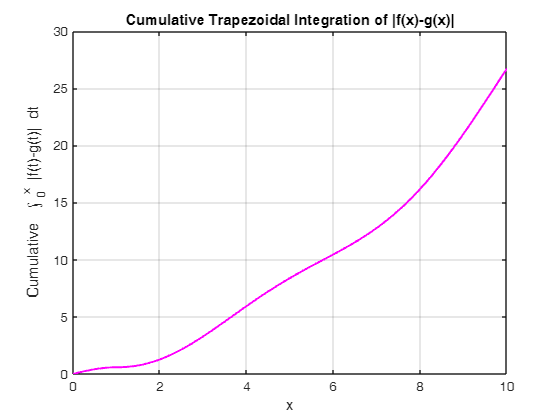


Y_cum = cumtrapz(x_plot, difference(x_plot));
figure;
plot(x_plot, Y_cum, 'm-', 'LineWidth', 1.5);
xlabel('x'); ylabel('Cumulative \int_{0}^{x} |f(t)-g(t)| dt');
title('Cumulative Trapezoidal Integration of |f(x)-g(x)|');
grid on;


syms xs ys
f_sym = xs*ys + ys^2;

int_x = int(f_sym, xs);
int_xy = int(int_x, ys);
disp('Indefinite integral ∫∫ f(x,y) dx dy:');

Indefinite integral ∫∫ f(x,y) dx dy:


disp(int_xy);

$$\frac{\mathrm{xs}\,{\mathrm{ys}}^{2}\,\left(3\,\mathrm{xs}+4\,\mathrm{ys}\right)}{12}$$


I_double = int(int(f_sym, xs, 0, 1), ys, 0, 2);
disp('Double integral of x*y + y^2 over x∈[0,1], y∈[0,2]:');

Double integral of x*y + y^2 over x∈[0,1], y∈[0,2]:


disp(I_double);

$$\frac{11}{3}$$


grad_f = @(x_val, y_val) [2*(x_val-2); 6*(y_val+1)];
pt = [3, 0];
grad_at_pt = grad_f(pt(1), pt(2));
disp('Gradient of (x-2)^2 + 3(y+1)^2 at (3,0):');

Gradient of (x-2)^2 + 3(y+1)^2 at (3,0):


disp(grad_at_pt);

     2
     6



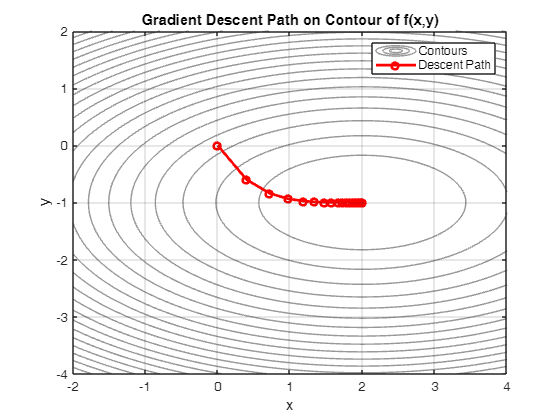


alpha = 0.1;
max_iter = 50;
x0 = [0; 0];

[points, values] = GradientDescent(@(u) (u(1)-2).^2 + 3*(u(2)+1).^2, @(xv,yv) [2*(xv-2); 6*(yv+1)], x0, alpha, max_iter);

[xg, yg] = meshgrid(linspace(-2, 4, 100), linspace(-4, 2, 100));
zg = (xg-2).^2 + 3*(yg+1).^2;
figure;
contour(xg, yg, zg, 20, 'LineColor', [0.6 0.6 0.6]); hold on;
plot(points(:,1), points(:,2), 'ro-', 'LineWidth', 2, 'MarkerSize', 5);
xlabel('x'); ylabel('y');
title('Gradient Descent Path on Contour of f(x,y)');
legend('Contours','Descent Path','Location','northeast');
grid on; hold off;


f_log = @(x) log(x);
x_val = 2;
h = 0.01;
df_approx = (f_log(x_val + h) - f_log(x_val - h)) / (2*h);
exact_df = 1 / x_val;
relative_error = abs(df_approx - exact_df) / abs(exact_df);
disp('Approximate derivative of ln(x) at x=2 using central difference:');

Approximate derivative of ln(x) at x=2 using central difference:


disp(df_approx);

    0.5000



disp('Exact derivative at x=2:');

Exact derivative at x=2:


disp(exact_df);

    0.5000



disp('Relative error:');

Relative error:


disp(relative_error);

   8.3335e-06




function [points, values] = GradientDescent(f, grad_f, x0, alpha, max_iter)
    points = zeros(max_iter+1, numel(x0));
    values = zeros(max_iter+1, 1);

    points(1, :) = x0(:).';
    values(1) = f(x0);

    current_x = x0;
    for iter = 1:max_iter
        g = grad_f(current_x(1), current_x(2));
        current_x = current_x - alpha * g;
        points(iter+1, :) = current_x(:).';
        values(iter+1) = f(current_x);
    end
end

## Fucntios

function SortingExample
    input = [3.5, -2, 7, 3.5, 8, -18, 7, 4.2];

    bubble_sorted = ReverseSortPositive(input);
    disp('Bubble Sort (Descending, Positives):');
    disp(bubble_sorted);

    merge_sorted = MergeSortPositive(input);
    disp('Merge Sort (Descending, Positives):');
    disp(merge_sorted);
end

function sorted_output = ReverseSortPositive(x)
    pos_x = x(x > 0);
    n = length(pos_x);
    for i = 1:n-1
        for j = 1:n-i
            if pos_x(j) < pos_x(j+1)
                temp = pos_x(j);
                pos_x(j) = pos_x(j+1);
                pos_x(j+1) = temp;
            end
        end
    end
    sorted_output = pos_x;
end

function sorted_output = MergeSortPositive(x)
    pos_x = x(x > 0);
    sorted_output = mergeSort(pos_x);
end

function arr = mergeSort(arr)
    if length(arr) <= 1
        return;
    end
    mid = floor(length(arr)/2);
    left = mergeSort(arr(1:mid));
    right = mergeSort(arr(mid+1:end));
    arr = merge(left, right);
end

function merged = merge(a, b)
    i = 1;
    j = 1;
    k = 1;
    merged = zeros(1, length(a) + length(b));
    while i <= length(a) && j <= length(b)
        if a(i) >= b(j)
            merged(k) = a(i);
            i = i + 1;
        else
            merged(k) = b(j);
            j = j + 1;
        end
        k = k + 1;
    end
    while i <= length(a)
        merged(k) = a(i);
        i = i + 1;
        k = k + 1;
    end
    while j <= length(b)
        merged(k) = b(j);
        j = j + 1;
        k = k + 1;
    end
end

SortingExample;

Bubble Sort (Descending, Positives):
    8.0000    7.0000    7.0000    4.2000    3.5000    3.5000

Merge Sort (Descending, Positives):
    8.0000    7.0000    7.0000    4.2000    3.5000    3.5000




function findPrimesTimed(n)
    tic
    primes = [];
    for k = 2:n
        isPrime = true;
        for j = 2:floor(sqrt(k))
            if mod(k, j) == 0
                isPrime = false;
                break;
            end
        end
        if isPrime
            primes(end+1) = k;
        end
    end
    disp('Prime numbers:')
    disp(primes)
    elapsed = toc;
    fprintf('Time taken: %.6f seconds\n', elapsed);
end

findPrimesTimed(100)

Prime numbers:
     2     3     5     7    11    13    17    19    23    29    31    37    41    43    47    53    59    61    67    71    73    79    83    89    97

Time taken: 0.024621 seconds


## Algorithm

clc; clear; close all;

f = @(x) x.^3 - x - 2;
df = @(x) 3*x.^2 - 1;

x0 = 1.5;
a = 1; b = 2;
tol = 1e-6;
max_iter = 50;

[root_newton, newton_steps] = newton_method(f, df, x0, tol, max_iter);
[root_bisection, bisection_steps] = bisection_method(f, a, b, tol, max_iter);

fprintf('Newton Method Root: %.8f\n', root_newton);

Newton Method Root: 1.52137971


fprintf('Bisection Method Root: %.8f\n', root_bisection);

Bisection Method Root: 1.52138042


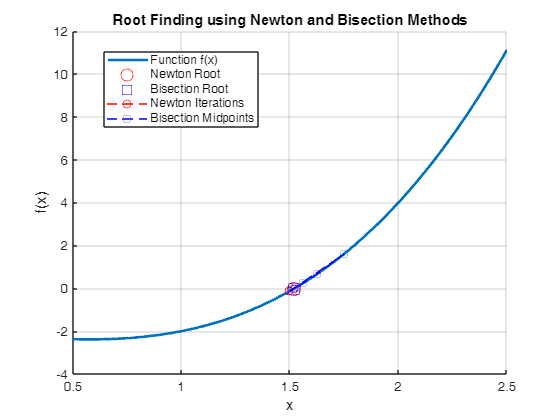


x_vals = linspace(a-0.5, b+0.5, 400);
figure; hold on; grid on;
plot(x_vals, f(x_vals), 'LineWidth', 2);
plot(root_newton, f(root_newton), 'ro', 'MarkerSize', 10, 'DisplayName', 'Newton Root');
plot(root_bisection, f(root_bisection), 'bs', 'MarkerSize', 10, 'DisplayName', 'Bisection Root');
plot(newton_steps, f(newton_steps), 'ro--', 'DisplayName', 'Newton Iterations');
plot(bisection_steps, f(bisection_steps), 'bs--', 'DisplayName', 'Bisection Midpoints');
xlabel('x');
ylabel('f(x)');
title('Root Finding using Newton and Bisection Methods');
legend('Function f(x)', 'Newton Root', 'Bisection Root', 'Newton Iterations', 'Bisection Midpoints', 'Location', 'best');
hold off;


function [root, steps] = newton_method(f, df, x0, tol, max_iter)
    x = x0;
    steps = zeros(1, max_iter+1);
    steps(1) = x0;
    for i = 1:max_iter
        x_new = x - f(x)/df(x);
        steps(i+1) = x_new;
        if abs(x_new - x) < tol
            root = x_new;
            steps = steps(1:i+1);
            return;
        end
        x = x_new;
    end
    root = x;
    steps = steps(1:end);
end

function [root, midpoints] = bisection_method(f, a, b, tol, max_iter)
    if f(a)*f(b) >= 0
        error('Function must have opposite signs at interval endpoints.');
    end
    midpoints = zeros(1, max_iter);
    for i = 1:max_iter
        c = (a + b)/2;
        midpoints(i) = c;
        if abs(f(c)) < tol || (b - a)/2 < tol
            root = c;
            midpoints = midpoints(1:i);
            return;
        end
        if f(c)*f(a) < 0
            b = c;
        else
            a = c;
        end
    end
    root = (a + b)/2;
    midpoints = midpoints(1:end);
end


## Linear system

function solution = solveLinearSystem(equations)
    syms_vars = sym([]);
    eqns = sym.empty(length(equations),0);
    for i = 1:length(equations)
        eqn_sym = str2sym(equations{i});
        vars = symvar(eqn_sym);
        syms_vars = union(syms_vars, vars);
        eqns(i) = eqn_sym;
    end
    sol = solve(eqns, syms_vars);
    solution = struct();
    for v = 1:length(syms_vars)
        var_name = char(syms_vars(v));
        solution.(var_name) = sol.(var_name);
    end
end

eqs = {
    '2*x + 3*y = 5'
    'x - y = 1'
};

sol = solveLinearSystem(eqs);
disp(sol);

    x: 8/5
    y: 3/5

